# List Selector Two Pane

The List Selector Two-Pane widget is similar to the one-pane variant. It is intended for adding items to a list from a known set. In this case, the set of available items is displayed in a list on the left side, and items are selectively added to the right list.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 300 215]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

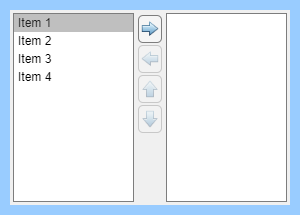

listWidget2 = wt.ListSelectorTwoPane(gridObj);

listWidget2.ValueChangedFcn = @(src,evt)disp(evt)

listWidget2 =   ListSelectorTwoPane with properties:

               ButtonPushedFcn: ''
               ValueChangedFcn: @(src,evt)disp(evt)
    HighlightedValueChangedFcn: ''

                         Items: ["Item 1"    "Item 2"    "Item 3"    "Item 4"]
                     ItemsData: [1×0 double]
                      Sortable: on
                 SelectedIndex: []
                         Value: [1×0 string]
              HighlightedValue: [1×0 string]
                   ButtonWidth: 28
                   UserButtons: [1×1 ButtonGrid]
                   ListButtons: [1×1 ButtonGrid]
                   ButtonColor: [0.9600 0.9600 0.9600]
                    FieldColor: [1 1 1]

                      Position: [11 11 280 195]
                         Units: 'pixels'

  Show 

Load an array of item names to include in the widget:

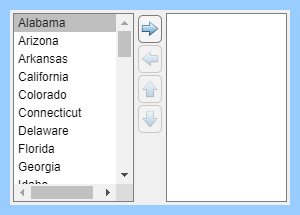

load("usastates.mat","usastates");
stateNames = string({usastates.Name});

listWidget2.Items = stateNames;

Set the initial selection:

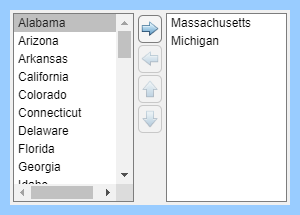

listWidget2.Value = ["Massachusetts","Michigan"];

Disable the ability to reorder the items on the right:

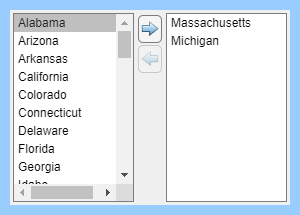

listWidget2.Sortable = "off";

Add a custom user button to the widget:

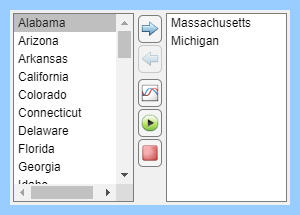

listWidget2.UserButtons.Icon = {"plot_24.png","play_24.png","stop_24.png"};
listWidget2.UserButtons.ButtonPushedFcn = @(src,evt)disp(evt);
listWidget2.UserButtons.ButtonHeight = [28,28,28];

*Copyright 2020-2025 The MathWorks, Inc.*